clear,clc,close all

syms theta_3 theta_4 theta_5 theta_6 theta_7 theta_8 omega_3 omega_4 omega_5 omega_6 omega_7 omega_8 alpha_3 alpha_4 alpha_5 alpha_6 alpha_7 alpha_8 T_1

F_12 = sym("F12", [2,1]);
F_32 = sym("F32", [2,1]);
F_43 = sym("F43", [2,1]);
F_54 = sym("F54", [2,1]);
F_14 = sym("F14", [2,1]);
F_65 = sym("F65", [2,1]);
F_16 = sym("F16", [2,1]);

r_1 = 96.033e-2;
r_2 = 48.5950e-2;
r_3 = 144.6281e-2;
r_4 = 131.14345e-2;
r_5 = 115.18102e-2;
r_6 = 145.7851e-2;
r_7 = 101.88468e-2;
r_8 = 50.9091e-2;
r_9 = 183.967e-2;

theta_1 = 0;
theta_2 = 143;
theta_9 = 0;
theta_34 = 12.20286392;
theta_54 = 84.23135997;
theta_14 = 11.69962314;

omega_1 = 0; 
omega_2 = 1;
omega_9 = 0; 

alpha_1 = 0; 
alpha_2 = 0;
alpha_9 = 0; 

rho_khati = 1;
rho_sathi = 1;

A_4 = 236842.80e-6;

m_2 = r_2 * rho_khati; 
m_3 = r_3 * rho_khati; 
m_4 = A_4 * rho_sathi;
m_5 = r_5 * rho_khati;
m_6 = r_6 * rho_khati;

I_2 = 9562985.85e-9;
I_3 = 252102293.4e-9; 
I_4 = 19849281.92e-9;
I_5 = 127339023.3e-9;
I_6 = 258201149.4e-9;

g = 9.81;
P = 200;
T= 20;

## Posture

% one loop
% posture analysis

theta2(1,1) = theta_2; 

% loop 1

eq(1) = real( r_2*exp(i*((theta2(1,end))*pi/180)) + r_3*exp(i*((theta_3)*pi/180)) + r_4*exp(i*((theta_4)*pi/180)) ) == real( r_1*exp(i*((theta_1)*pi/180)) );
eq(2) = imag( r_2*exp(i*((theta2(1,end))*pi/180)) + r_3*exp(i*((theta_3)*pi/180)) + r_4*exp(i*((theta_4)*pi/180)) ) == imag( r_1*exp(i*((theta_1)*pi/180)) );

[theta3(1,1) theta4(1,1)] = vpasolve([eq(1) eq(2)] , [theta_3 theta_4] , [43 , 282])

$$theta3 = 42.999997806424723608776145950754$$

$$theta4 = 282.80616413988310970115282074114$$


% loop 2

eq(3) = real( r_4*exp(i*((theta4(1,end))*pi/180)) + r_7*exp(i*((theta_7)*pi/180)) ) == real( r_8*exp(i*((theta_8)*pi/180)) );
eq(4) = imag( r_4*exp(i*((theta4(1,end))*pi/180)) + r_7*exp(i*((theta_7)*pi/180)) ) == imag( r_8*exp(i*((theta_8)*pi/180)) );

[theta7(1,1) theta8(1,1)] = vpasolve([eq(3) eq(4)] , [theta_7 theta_8] , [82 , 328])

$$theta7 = 82.042383028471039052797130063764$$

$$theta8 = 327.99999399527402342465346972675$$


% loop 3

eq(5) = real( r_7*exp(i*((theta7(1,end))*pi/180)) + r_5*exp(i*((theta_5)*pi/180)) ) == real( r_6*exp(i*((theta_6)*pi/180)) + r_9*exp(i*((theta_9)*pi/180)) );
eq(6) = imag( r_7*exp(i*((theta7(1,end))*pi/180)) + r_5*exp(i*((theta_5)*pi/180)) ) == imag( r_6*exp(i*((theta_6)*pi/180)) + r_9*exp(i*((theta_9)*pi/180)) );

[theta5(1,1) theta6(1,1)] = vpasolve([eq(5) eq(6)] , [theta_5 theta_6] , [16 , 114])

$$theta5 = 16.27420917737752338052403263085$$

$$theta6 = 113.99999776278688430933035056382$$

% other loops
for j = 0 : 5 : 10 * 180 / pi
   
    theta_2 = theta_2 + 5;
    theta2(1,1+end) = theta_2;

    eq(1) = real( r_2*exp(i*((theta2(1,end))*pi/180)) + r_3*exp(i*((theta_3)*pi/180)) + r_4*exp(i*((theta_4)*pi/180)) ) == real( r_1*exp(i*((theta_1)*pi/180)) );
    eq(2) = imag( r_2*exp(i*((theta2(1,end))*pi/180)) + r_3*exp(i*((theta_3)*pi/180)) + r_4*exp(i*((theta_4)*pi/180)) ) == imag( r_1*exp(i*((theta_1)*pi/180)) );
    
    [theta3(1,1+end), theta4(1,1+end)] = vpasolve([eq(1) eq(2)] , [theta_3 theta_4] , [43 , 282]);
    
    % loop 2
    
    eq(3) = real( r_4*exp(i*((theta4(1,end))*pi/180)) + r_7*exp(i*((theta_7)*pi/180)) ) == real( r_8*exp(i*((theta_8)*pi/180)) );
    eq(4) = imag( r_4*exp(i*((theta4(1,end))*pi/180)) + r_7*exp(i*((theta_7)*pi/180)) ) == imag( r_8*exp(i*((theta_8)*pi/180)) );
    
    [theta7(1,1+end) theta8(1,1+end)] = vpasolve([eq(3) eq(4)] , [theta_7 theta_8] , [82 , 328]);
    
    % loop 3
    
    eq(5) = real( r_7*exp(i*((theta7(1,end))*pi/180)) + r_5*exp(i*((theta_5)*pi/180)) ) == real( r_6*exp(i*((theta_6)*pi/180)) + r_9*exp(i*((theta_9)*pi/180)) );
    eq(6) = imag( r_7*exp(i*((theta7(1,end))*pi/180)) + r_5*exp(i*((theta_5)*pi/180)) ) == imag( r_6*exp(i*((theta_6)*pi/180)) + r_9*exp(i*((theta_9)*pi/180)) );
    
    [theta5(1,1+end) theta6(1,1+end)] = vpasolve([eq(5) eq(6)] , [theta_5 theta_6] , [16 , 114]);

   
end

% Ploting posture analysis

t = 0 : 10/length(0 : 5 : 10 * 180 / pi) : 10;
disp('theta2')

theta2


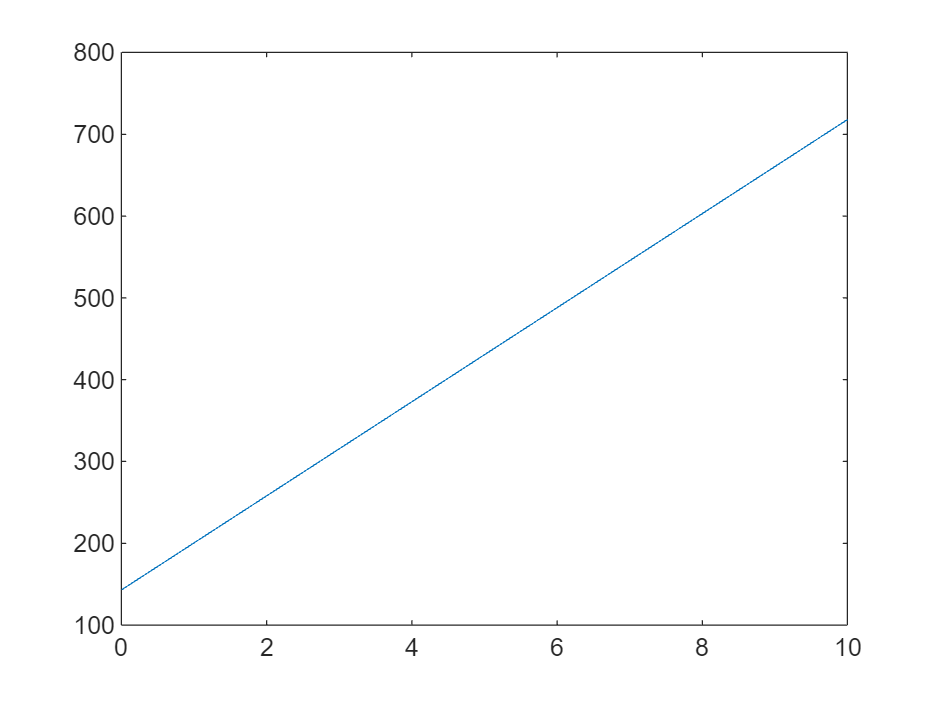

plot(t,theta2)

disp('theta3')

theta3


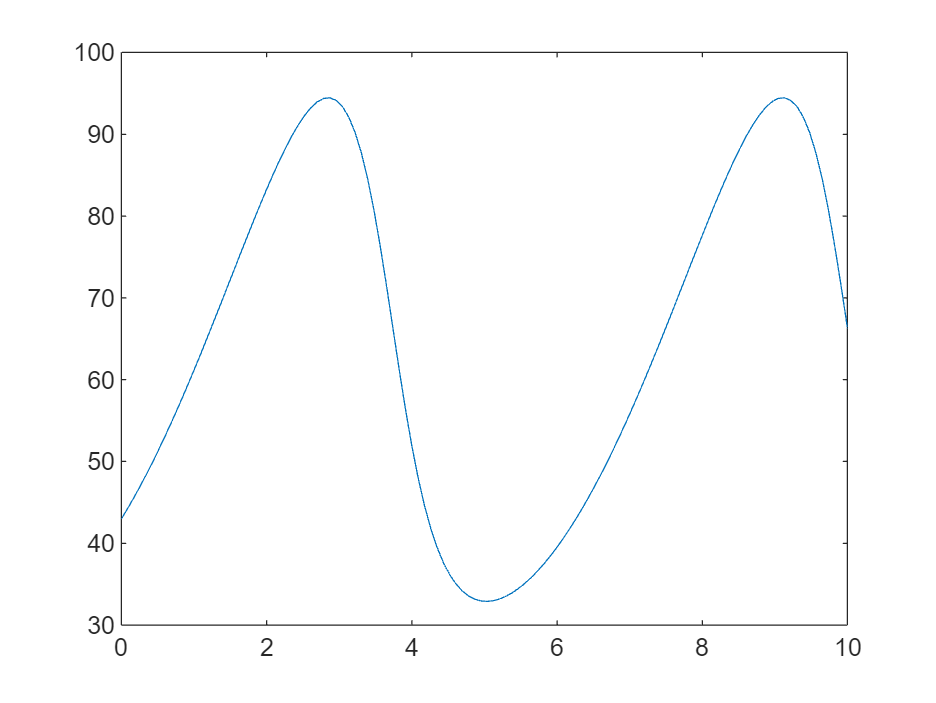

plot(t,theta3)

disp('theta4')

theta4


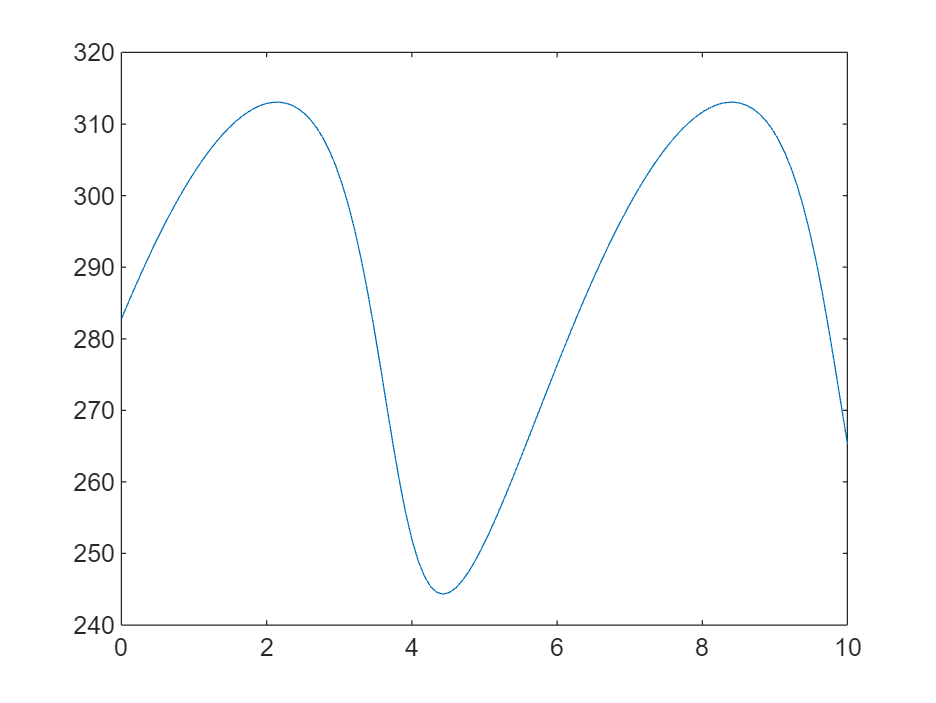

plot(t,theta4)

disp('theta5')

theta5


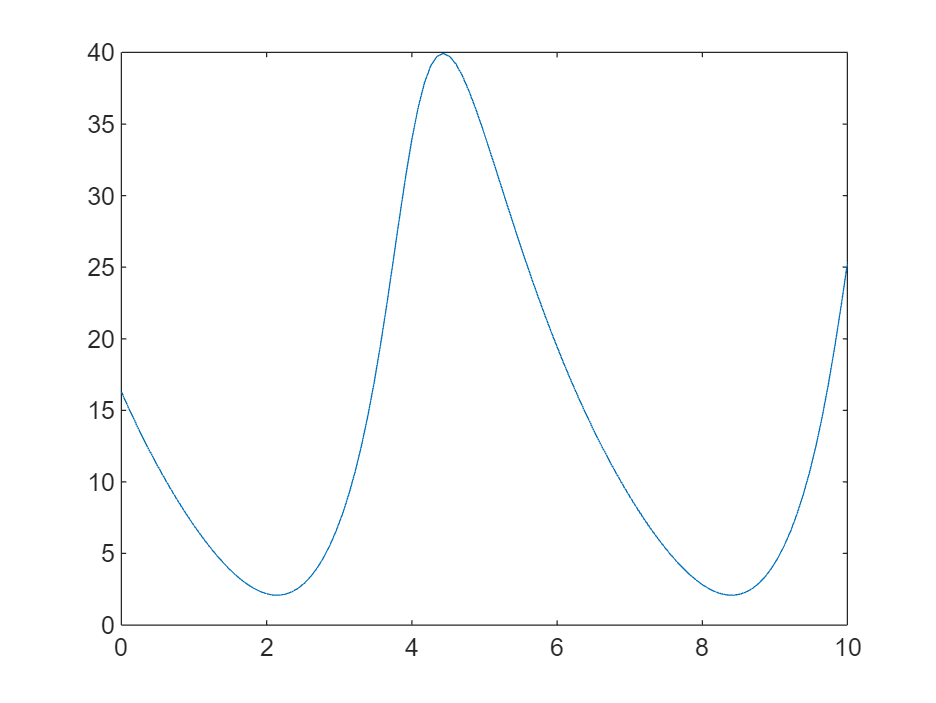

plot(t,theta5)

disp('theta6')

theta6


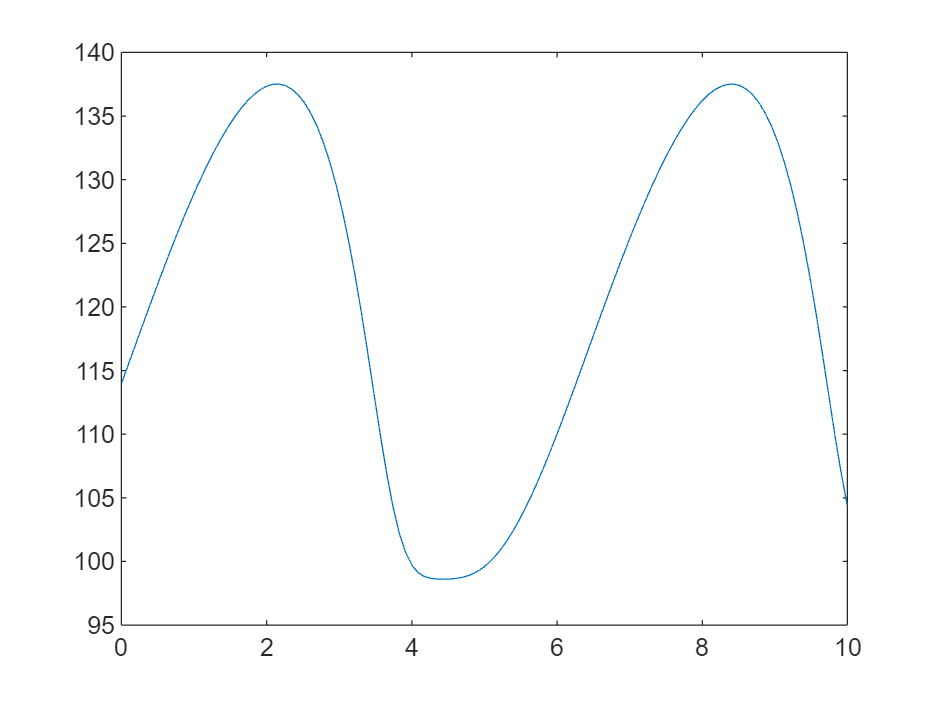

plot(t,theta6)

disp('theta7')

theta7


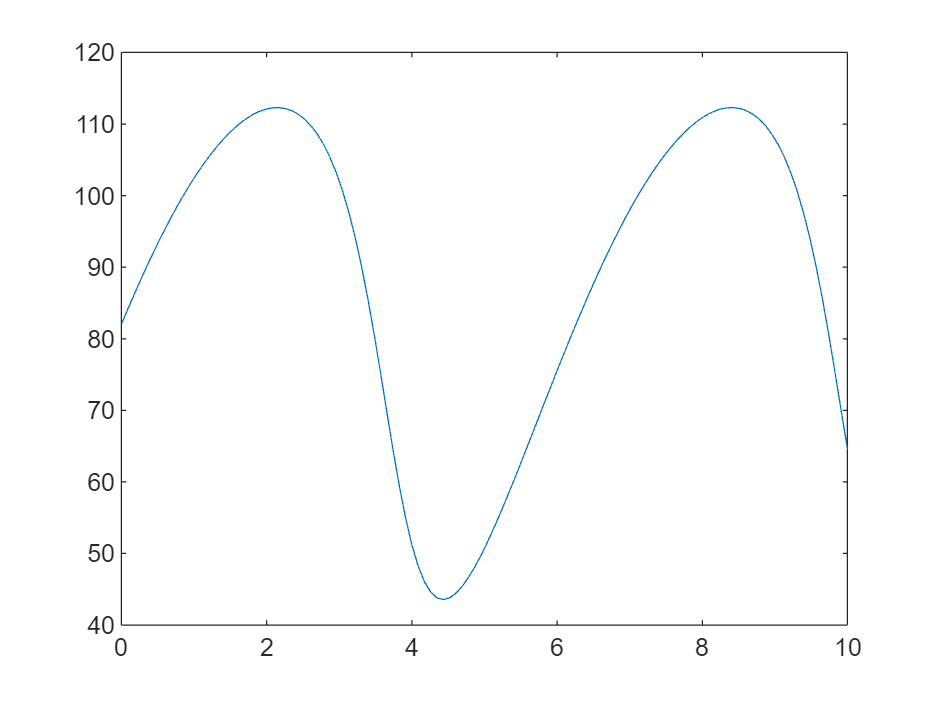

plot(t,theta7)

disp('theta8')

theta8


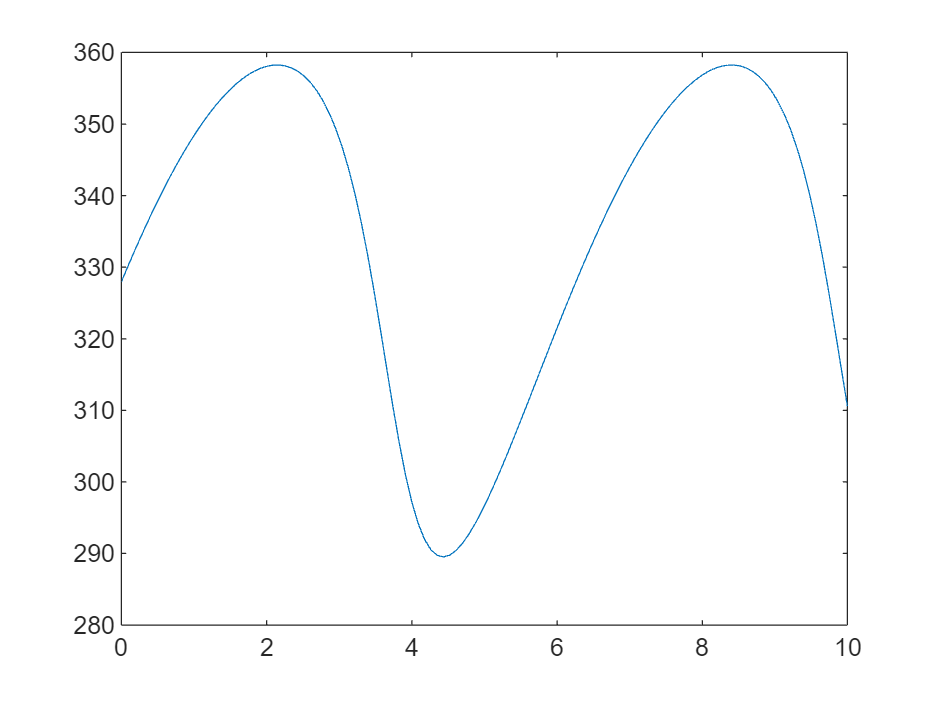

plot(t,theta8)

## Animation

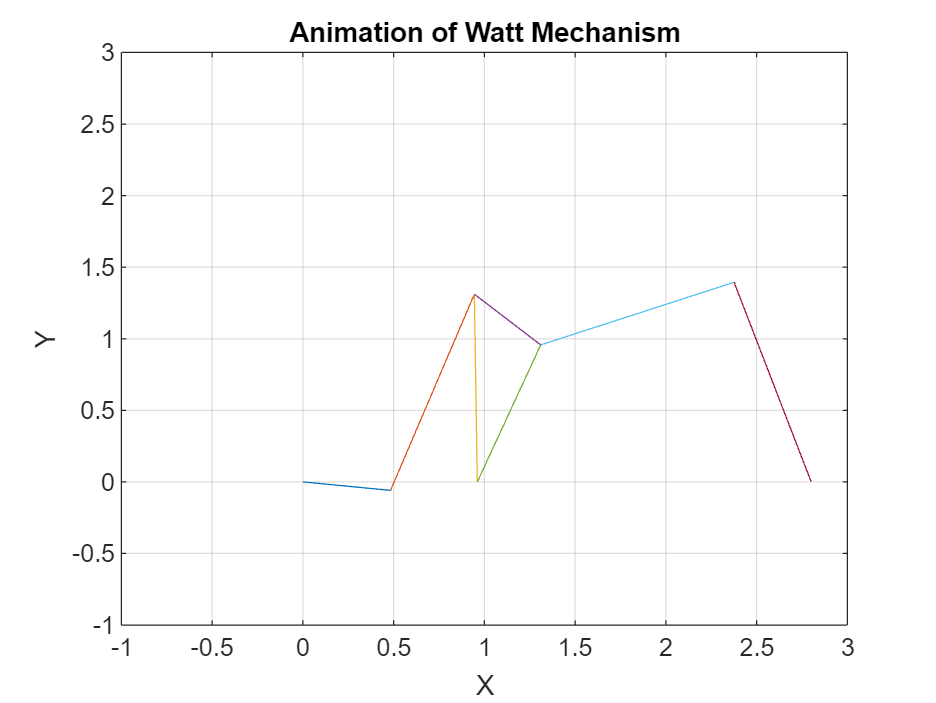

k=1;
for j = 0 : 5 : 10 * 180 / pi

    n2 = [cosd(theta2(1,k)) , sind(theta2(1,k))];

    n3 = [cosd(theta3(1,k)) , sind(theta3(1,k))];

    n4 = [cosd(theta7(1,k)+theta_14) , sind(theta2(1,k)+theta_14)];

    n5 = [cosd(theta5(1,k)) , sind(theta5(1,k))];

    n6 = [cosd(theta6(1,k)) , sind(theta6(1,k))];

    n7 = [cosd(theta7(1,k)) , sind(theta7(1,k))];

    pos_A = [0 , 0];
    pos_E = [r_1 , 0];
    pos_F = [r_1 + r_9 , 0];
    pos_B = r_2 * n2;
    pos_C = pos_B + r_3 * n3;
    pos_H = pos_E + r_7 * n7;
    pos_D = pos_F + r_6 * n6;

    k=k+1;
    
    plot([pos_A(1),pos_B(1)],[pos_A(2),pos_B(2)])
    hold on
    ylim([-1,3])
    xlim([-1,3])
    title('Animation of Watt Mechanism')
    xlabel('X')
    ylabel('Y')
    grid on
    plot([pos_B(1),pos_C(1)],[pos_B(2),pos_C(2)])
    plot([pos_C(1),pos_E(1)],[pos_C(2),pos_E(2)])
    plot([pos_C(1),pos_H(1)],[pos_C(2),pos_H(2)])
    plot([pos_E(1),pos_H(1)],[pos_E(2),pos_H(2)])
    plot([pos_D(1),pos_H(1)],[pos_D(2),pos_H(2)])
    plot([pos_D(1),pos_F(1)],[pos_D(2),pos_F(2)])
    pause(0.001)
    hold off
end